# Deforestation radius estimation

This code estimates how much the same synapse moves between the two imaging sessions. To do so - 4 fish were imaged with with the same time interval as during the training , same synapses were manually segmented in time point 1 and time point 2.

## load utility functions

cd 'D:\Code\repos\synapse-redistribution\get_data'
addpath('utils');

## load segmented synapses 

%% Rigid 
PERK_RES = [0.2075665 0.2075665 0.6016173];
% Path = 'D:\TR01\pERK\20190626_SingleCell';
mainFolder = 'C:\Users\nadtochi\Dropbox\2019_LearningPaper\Single_Cell_Photoconversion_ForSpineQuantification\';

Path = [mainFolder,'2019-06-26_Dendra_single_cell_2_tp'];
extraFolder = 'processed';
csvName = 'Fish3-pERK cell-one day later-tp1-single channel';
fishName = 'Fish3_2019_06_26';
synapses = load_timepoints(1,[],Path,csvName,fishName,extraFolder,[1 1 0.602],[1 1 1]);

Path = [mainFolder,'2019-07-19_Dendra_single_cells_2_timepoints\Fish2'];
extraFolder = 'preprocessed';
csvName = 'Fish2-pERK neuron 3days later-TP1';
fishName = 'Fish2_2019_07_19';
synapses = load_timepoints(2,synapses,Path,csvName,fishName,extraFolder,[1 1 PERK_RES(3)],[1 1 1]);

Path = [mainFolder,'2019-07-19_Dendra_single_cells_2_timepoints\Fish9'];
extraFolder = 'preprocessed';
csvName = 'Fish9 tp1';
fishName = 'Fish9_2019_07_19';
synapses = load_timepoints(3,synapses,Path,csvName,fishName,extraFolder,[1 1 PERK_RES(3)],PERK_RES);

Path = [mainFolder,'2019-08-07_MemDendra_single_Cells_2TP\Fish9'];
extraFolder = 'preprocesses';
csvName = 'Fish9-pERK_singleCell_1DayLater_Tpt1';
fishName = 'Fish9_2019_08_07';
synapses = load_timepoints(4,synapses,Path,csvName,fishName,extraFolder,[1 1 PERK_RES(3)],[1 1 1]);
   

## get distances

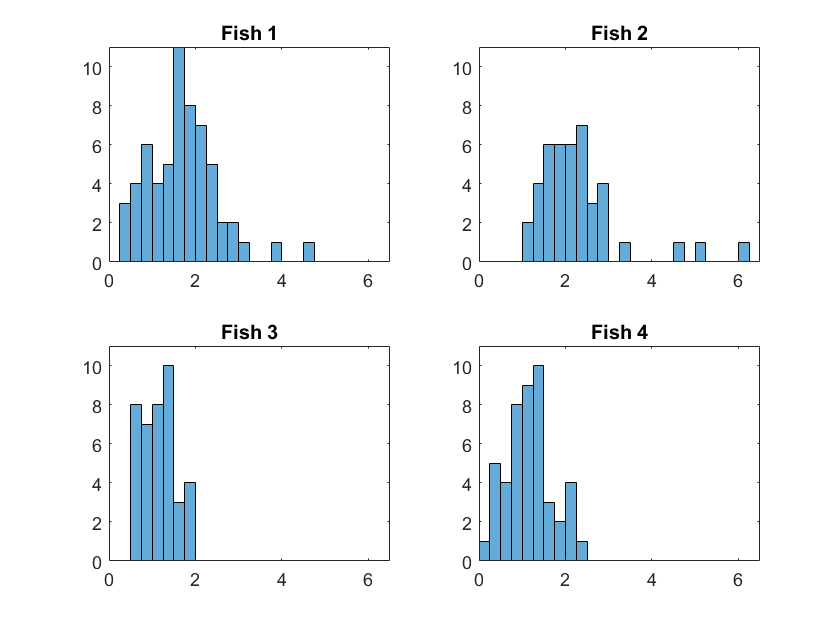

diff_3d = cell(1,4);

figure;
for iFish = 1:4
subplot(2,2,iFish);
diff_3d{iFish} = get_distances(synapses.tp1{iFish},synapses.tp2{iFish});
histogram(diff_3d{iFish},'BinWidth',0.25)
xlim([0 6.5])
ylim([0 11])
title(['Fish ',num2str(iFish)])

end

## save distances as csv

maxPairs = max([length(diff_3d{1}),length(diff_3d{2}),length(diff_3d{3}),length(diff_3d{4})]);
nanArr = nan(maxPairs,4);
nanArr(1:length(diff_3d{1}),1) = diff_3d{1};
nanArr(1:length(diff_3d{2}),2) = diff_3d{2};
nanArr(1:length(diff_3d{3}),3) = diff_3d{3};
nanArr(1:length(diff_3d{4}),4) = diff_3d{4};

t = table(nanArr(:,1),nanArr(:,2),nanArr(:,3),nanArr(:,4));
t.Properties.VariableNames = synapses.id

t = 60×4 table
    Fish3_2019_06_26    Fish2_2019_07_19    Fish9_2019_07_19    Fish9_2019_08_07
    ________________    ________________    ________________    ________________

         1.5471              5.0675              1.1879             0.42449     
        0.94845              3.2529              1.3918             0.82991     
         1.3187              2.3433             0.88485             0.42947     
         1.4499               1.853             0.85324              1.0801     
         1.7061               2.217             0.67395              1.3463     
         1.6852              1.9476              1.5468              1.0101     
         2.0719              1.1213              1.2313             0.98249     
         2.3159              2.1957              1.2074             0.52724     
        0.88489               2.469   

writetable(t,[mainFolder,'PairwiseDistance_4Fish.csv']);

## plot distances all together

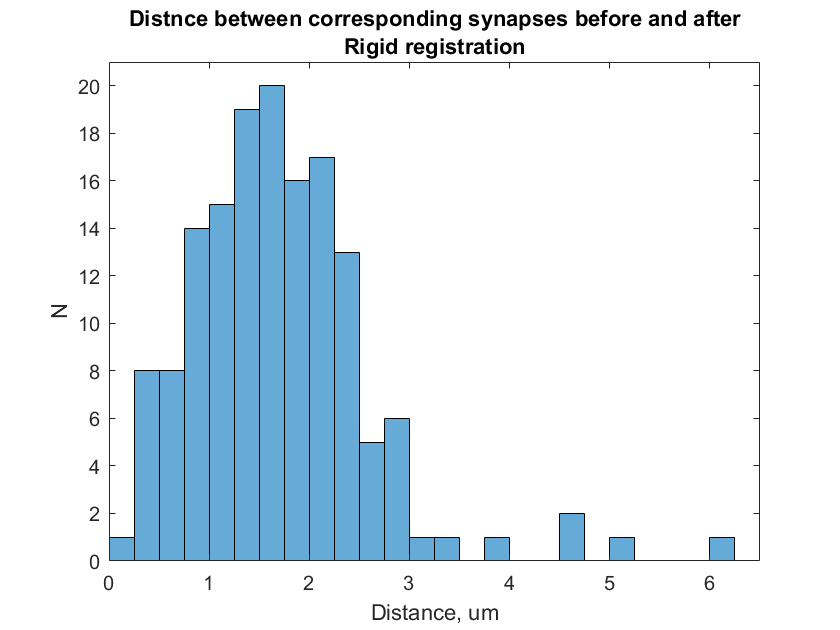

figure
diff_3d = get_distances(cat(1,synapses.tp1{1},synapses.tp1{2},synapses.tp1{4}),cat(1,synapses.tp2{1},synapses.tp2{2},synapses.tp2{4}));
histogram(diff_3d,'BinWidth',0.25)
title({'Distnce between corresponding synapses before and after';'Rigid registration'})
xlabel('Distance, um');
ylim([0 21]);
xlim([0 6.5]);
ylabel('N');

**HELPER FUNCTIONS**

function diff_3d = get_distances(synapses_tp1,synapses_tp2)
diff_tp = synapses_tp1 - synapses_tp2;
diff_3d = sqrt(sum(diff_tp.^ 2,2));
end

function plot_pairs(diff_3d,synapses_tp1,synapses_tp2,thr)
plot3(synapses_tp1(:,1),synapses_tp1(:,2),synapses_tp1(:,3),...
    '.','MarkerSize',15)
hold on
plot3(synapses_tp2(:,1),synapses_tp2(:,2),synapses_tp2(:,3),...
    '.','MarkerSize',15)
xlabel('X, um');
ylabel('Y, um');
zlabel('Z, um');

% thr = 0;
for i_pair = 1:length(diff_3d)
    if diff_3d(i_pair)>thr
        hold on
        plot3([synapses_tp1(i_pair,1),synapses_tp2(i_pair,1)],...
            [synapses_tp1(i_pair,2),synapses_tp2(i_pair,2)],...
            [synapses_tp1(i_pair,3),synapses_tp2(i_pair,3)],'Color',[0 0 0]);
    end
end
end

function synapses = load_timepoints(iCell,synapses,Path,csvName,fishName,extrafolder,PERK_RES1,PERK_RES2)

synapses_csv = readtable([Path,...
    '\',csvName,'.csv']);
synapses.tp1{iCell} = [synapses_csv.X synapses_csv.Y synapses_csv.Slice].*PERK_RES1;

synapses_csv = readtable([Path,...
    '\',extrafolder,'\points_tp2TOtp1_Rigid.csv']);
if ~ismember('Z', synapses_csv.Properties.VariableNames)
    synapses.tp2{iCell} = [synapses_csv.X synapses_csv.Y synapses_csv.Slice].*PERK_RES2;
else
    synapses.tp2{iCell} = [synapses_csv.X synapses_csv.Y synapses_csv.Z].*PERK_RES2;
end
synapses.id{iCell} = fishName;

end
